#     DC-8 AIRCRAFT Lateral Equations of Motions

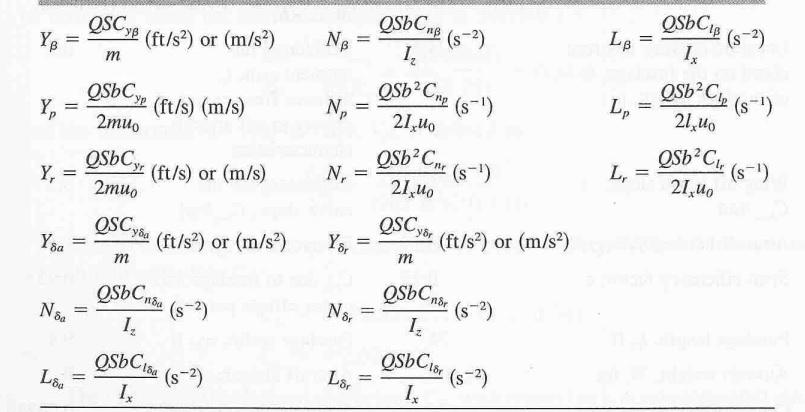

Yv =-0.0868;
Yp = 0;
q = 270;
S = 2600;
c = 23;
b = 142.3;
cybeta = -0.7277;
cyr = 0;
m = 7143;
g0 = 32.086614;
M = 0.84;
a = 982;
u0 = M*a;
Yr = q*S*b*cyr/(2*m*u0);
Lr = 0.334;
Nv = 2.14;
Np = -0.0204;
Nr = -0.228;
theta = 0;
Lp = -1.181;
clp = -0.516;
Ixz = 45000;
Ix = 3770000;
Iz = 7130000;
ix = Ixz/Ix;
iz = Ixz/Iz;
clbeta = -0.16732;
Ydelta_r = 0.0222;
Ldelta_r = 0.549;
Ldelta_a = -2.11;
N_deltar = -0.01164;
N_deltaa = -0.0652;
Lv = (q*S*b*clbeta)/(Ix*u0);
cnbeta = 0.15471;
Nbeta = q*S*b*cnbeta/Iz;
Lbeta = -4.41;
Ybeta = q*S*cybeta/m;
A = [Yv,Yp,g0*cos(theta),Yr-u0;
    Lv,Lp,0,Lr;
    0,1,0,0;
    Nv,Np,0,Nr]

A =    -0.0868         0   32.0866 -824.8800
   -0.0054   -1.1810         0    0.3340
         0    1.0000         0         0
    2.1400   -0.0204         0   -0.2280


B = [Ydelta_r,0;
    Ldelta_r, Ldelta_a;
    0,0;
    N_deltar,N_deltaa];
C = [0,1,0,0;
    0,0,0,1];
D = [0,0;0,0];
eigs = eig(A) %Finding eigenvalues of A matrix

eigs =   -0.1573 +42.0150i
  -0.1573 -42.0150i
  -1.1920 + 0.0000i
   0.0109 + 0.0000i



$$$\lambda_{DR} = $$
 
$$-0.1573 \pm 42.0144j$$



$$\lambda_{roll} = -1.1920$$



$$\lambda_{spiral} =  0.00109$$



$$\zeta_{DR} = \sqrt{\frac{1}{1+\big(\frac{\eta}{\xi}\big)^2}}$$



$$\omega_{dr} = \frac{-\xi_{DR}}{\zeta_{DR}}$$


By using these equations the corresponding values are:

zeta_dr = sqrt(1/(1+(42.0144/-0.1765)^2));
wn_dr = 0.1765/(zeta_dr);
s = tf('s');
G_DR = (wn_dr^2)/(s^2+2*wn_dr*zeta_dr*s+wn_dr^2)

G_DR =
 
          1765
  --------------------
  s^2 + 0.353 s + 1765
 
Continuous-time transfer function.



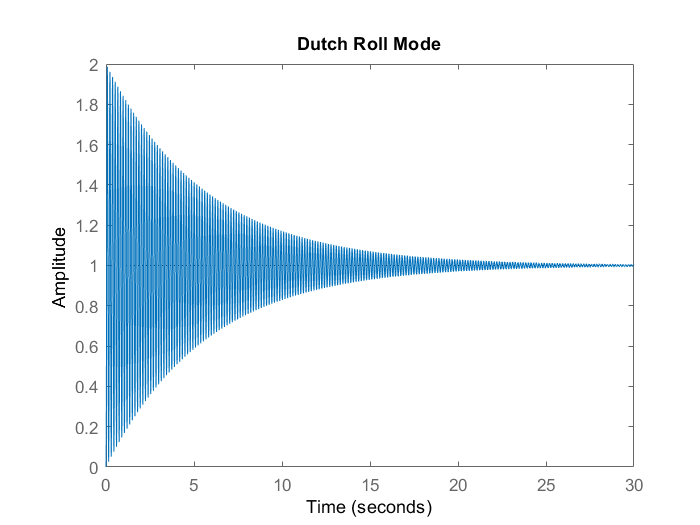

step(G_DR)
title("Dutch Roll Mode")

The general type of the second order equations is:$$\frac{\omega_n^2}{s^2+2*\zeta*\omega_n*s+\omega_n^2}$

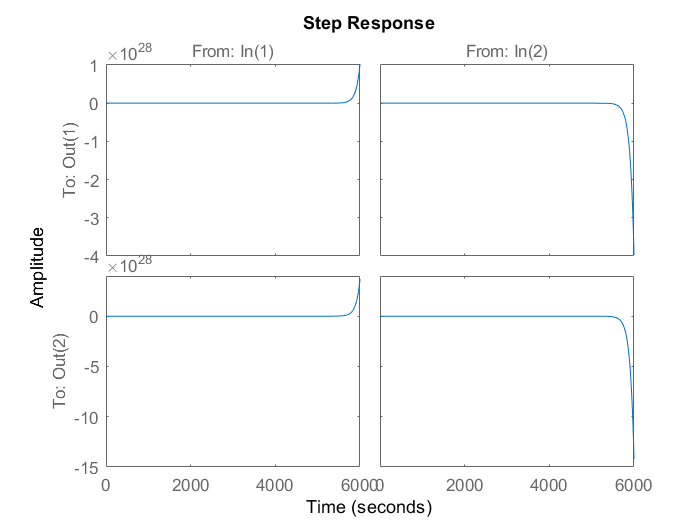

sys = ss(A,B,C,D);
G_sys = tf(sys);
step(G_sys);

figure(1)



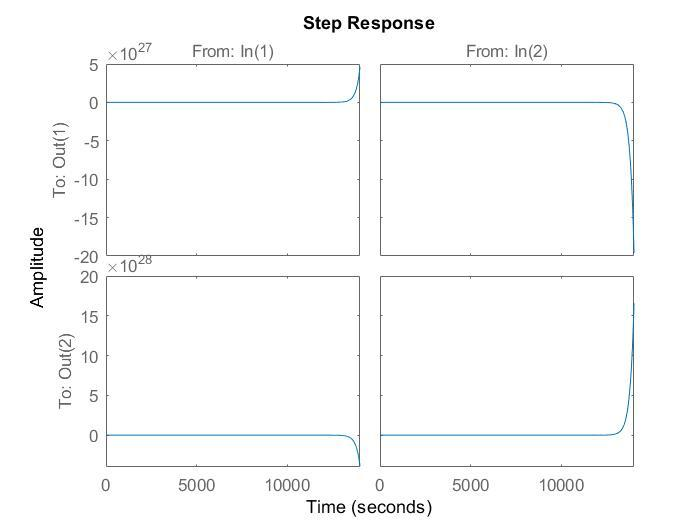

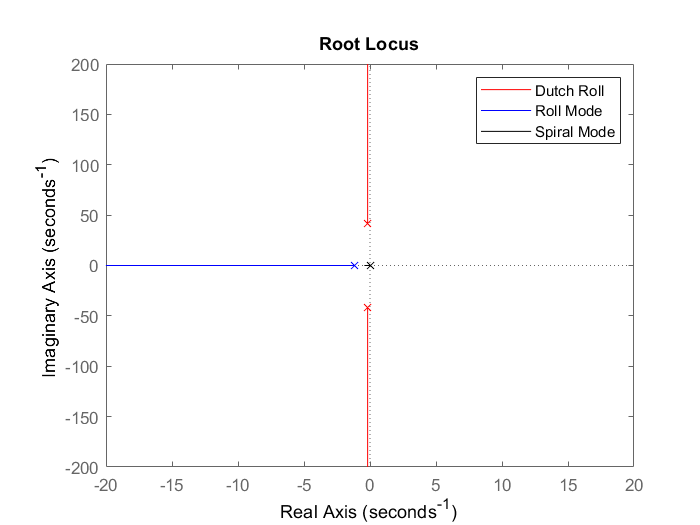

G_DR = wn_dr^2/(s^2+2*wn_dr*zeta_dr*s+wn_dr^2);
figure(2)
rlocus(G_DR,"r")
hold on
G_roll = (1/(s+1.192));

rlocus(G_roll,"b")
G_spiral = (1/(s-0.0109));
rlocus(G_spiral,"k")
hold off
legend("Dutch Roll","Roll Mode","Spiral Mode");

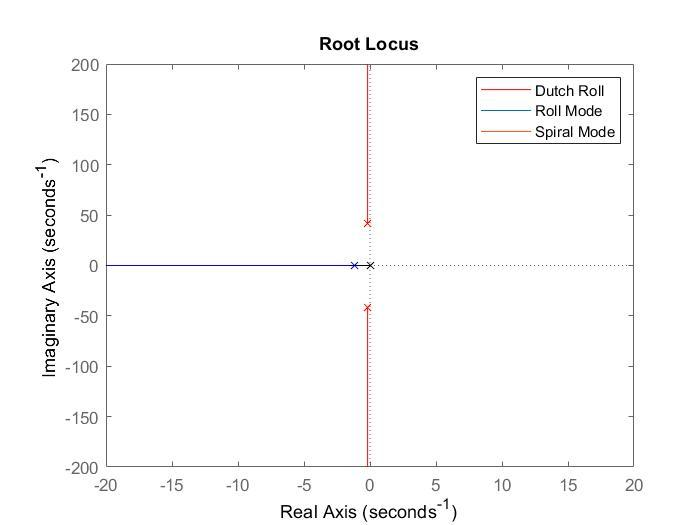

$$\lambda=$$$\frac{L_p+i_xN_p}{1-i_xi_z}$ This equation dominated by Lp 


$$\lambda \cong L_p$$


## Rolling Mode Approximation

lamda_rl_appr = Lp;

wn_rolling = 1.1920

From this calculation, $$\lambda_{apprx}$$ $\cong \lambda_{roll}$


$$\lambda_{roll} = -1.1475$$


$\lambda_{appr} = -1.181$ This is acceptable.

## Spiral Mode Approximation

lambda_spiral = Nr-(Lr*Nbeta)/(Lbeta)

lambda_spiral = -0.0638

wn_spiral = -0.0109


$$$\lambda_{apprx} = -0.0659$$$



$$\lambda_{spiral} =  0.046$$


As we see, it is not a good approximation.

## Dutch Roll Mode Approximation

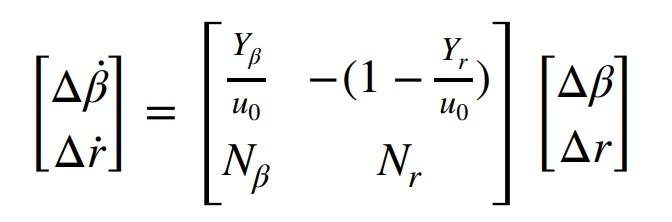

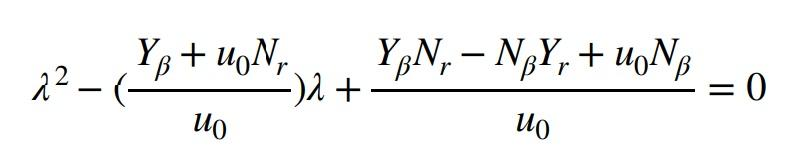

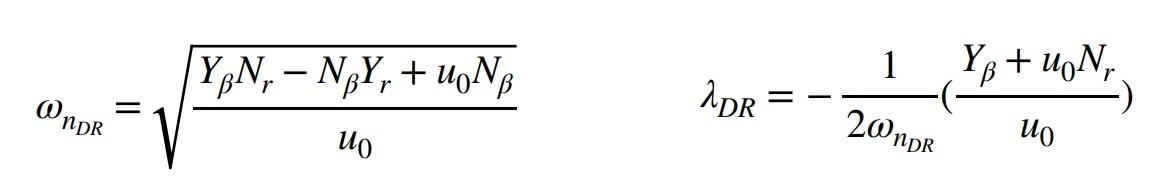

By using equations which are given above, dutch roll approximation $\omega$ and $\lambda$ values are calculating belowe

According to other reference which Cornell University Introduction to Aircraft Stability and Control lessons documents:


$$\omega_n^2=\frac{u_0\bigg(L_pN_v-N_pL_v\bigg)}{L_p+N_r}$$
 

wn_dr_appr = sqrt((Ybeta*Nr-Nbeta*Yr+u0*Nbeta)/u0);
lambda_dr_appr = (-1/(2*wn_dr))*((Ybeta+u0*Nr)/u0);
other_reference_book = sqrt((u0*(Lp*Nv-Lv*Np))/(Lp+Nr));